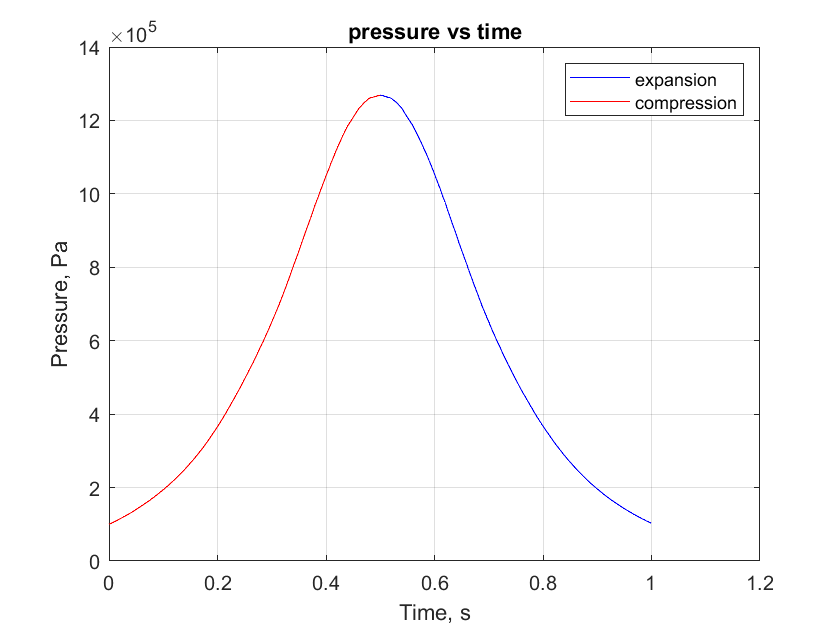

clear all; close all; clc;
% note to launch ansis fluen type fluent and not ansys

%all units base SI

% Problem 1
%data from piston moveing
A = importdata("volume-averaged-density-rfile_6_1.out");
volumeAveragedDenity = A.data;
%first col it timestep
%second col is density
%third col is physical time (as measured with a chronometer)
d = volumeAveragedDenity(:,2);

B = importdata("volume-averaged-pressure-rfile_6_1.out");
volumeAveragedPressure = B.data;
%first col it timestep
%second col is pressure
%third col is physical time (as measured with a chronometer)
p = volumeAveragedPressure(:,2);

[~, mindex] = max(p);

%problem 2
t = volumeAveragedPressure(:,3); % both pressure and density will have the same time and timesetp
figure(1);

plot(t,p,'b'); grid on;
hold on
plot(t(1:mindex),p(1:mindex),'r'); grid on;
legend("expansion","compression")
title("pressure vs time"); xlabel("Time, s"); ylabel("Pressure, Pa");

disp("0-.49: compression. .5-1: expansion.")

0-.49: compression. .5-1: expansion.


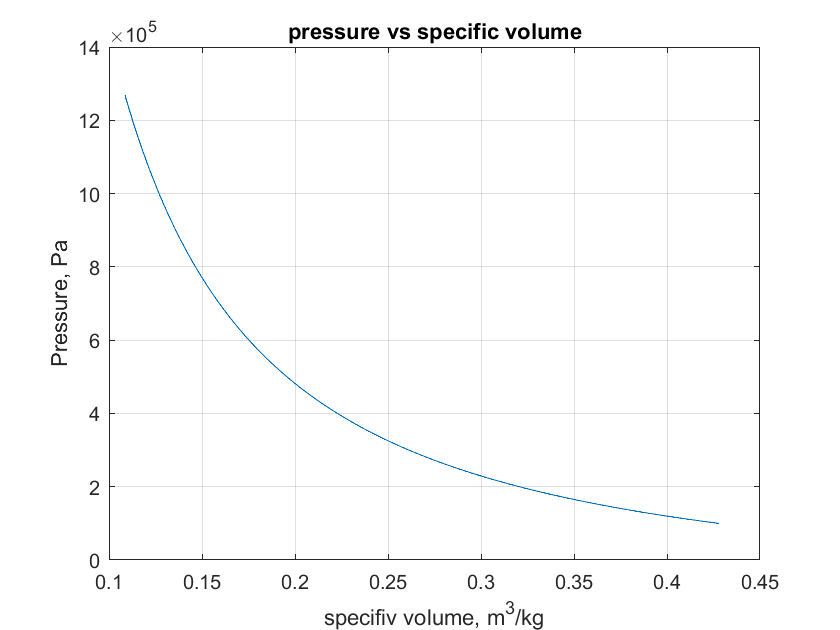


%problem 3
v = 1./d;
figure(2);
plot(v,p); grid on;
title("pressure vs specific volume"); xlabel("specifiv volume, m^3/kg"); ylabel("Pressure, Pa");

disp("due to no heat loass both expansion and compression are on top of each other")

due to no heat loass both expansion and compression are on top of each other



%problem 4
%use a rienman sum to aprox integral for work
% dw(1) = p(1)*v(1);
% for i = 2:mindex;
%     dw(i) = p(i)*v(i)-v(i-1);
% end
% wc = sum(dw) %for work of just expansion or just compression is w/2
% 
% dw(mindex) = p(mindex)*v(mindex);
% for i = mindex+1:length(p);
%     dw(i) = p(i)*v(i)-v(i-1);
% end
% we = sum(dw) %for work of just expansion or just compression is w/2

disp("they are different because of numerical error in the simulation and the trapezoidal integration")

they are different because of numerical error in the simulation and the trapezoidal integration



wc = trapz(v(1:mindex),p(1:mindex),1)

wc = -1.2479e+05

we = trapz(v(mindex:end),p(mindex:end),1)

we = 1.2440e+05


disp("because they are adiabatic the work done by copress and expand is same")

because they are adiabatic the work done by copress and expand is same


%problem 5
cp =662.66;
mw = 28.966;
Ru = 8314;
R = Ru/mw;
cv = cp - R;
gamma = cp/cv;

%calculate the work here
%see slide for formula
%w = intergral of p dv
%pv^gamma = const
p(1)*v(1)^gamma;
%W = (max(p)*min(v)-min(p)*max(v)) / (1-gamma) % this is probalby worng

syms press vol
const = (p(1)*v(1)^gamma);
integral(@(vol) const./vol.^gamma, v(1), v(mindex)) %this is aproximatly half of work found from integration of data

ans = -1.0360e+05

vpa(int(const/vol^gamma, vol, v(1), v(mindex))) %this is aproximatly half of work found from integration of data

$$ans = -103597.56678397775614630449560709$$


%(p(mindex)*v(mindex)-p(1)*v(1)) / (gamma-1) % for some reason this is twice what i get from numeric integration

W = (const/(1-gamma)) * (1/(v(mindex)^(gamma-1)) - 1/(v(1)^(gamma-1)))

W = -1.0360e+05


disp("differences are due to errors of numerical aproches to caclulations and numerical error in simulations")

differences are due to errors of numerical aproches to caclulations and numerical error in simulations
